# Diagram of signal processing  

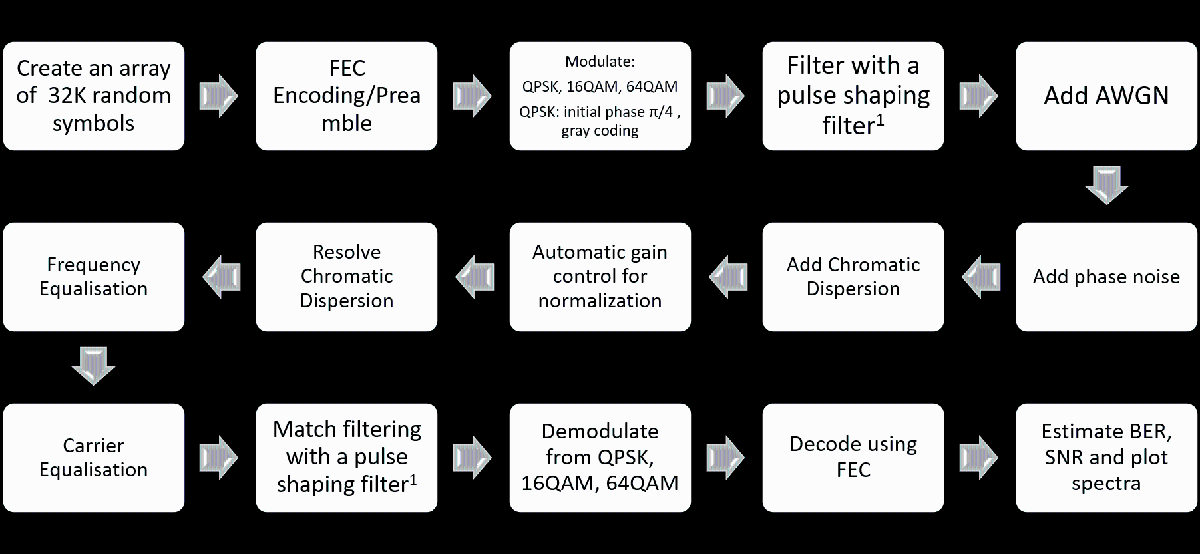

## Constants and Initial Conditions

%Resetting the rng seed
rng("default");
rng(1960);

enable_FEC = false;
enable_pulse_shaping = false;
enable_AWGN = true;
enable_phase_noise = false;
enable_chromatic_dispersion = false;
enable_frequency_equal = false;
enable_carrier_equal = false;
enable_plots = false;

num_symbols = 32*1024; 
symbol_rate = 100e9;
time_step = 1/symbol_rate;
linewidth = 100e3;
variance = 2*pi*linewidth*time_step;

## Forward Error Correction

if enable_FEC
    symbols_b = zeros(1,num_symbols);
    symbols_q = zeros(1,num_symbols);
    symbols_16 = zeros(1,num_symbols);
    symbols_64 = zeros(1,num_symbols);
end
%To be Implemented

## Modulation

%BPSK
M = 2;
if (~enable_FEC)
symbols_b = randi([0 M-1],1,num_symbols);
end
bpsk_mod = pskmod(symbols_b,M,0,'gray');


%QPSK
M = 4;
if (~enable_FEC)
symbols_q = randi([0 M-1],1,num_symbols);
end
qpsk_mod = pskmod(symbols_q,M,pi/M,'gray');


%16QAM
M = 16;
if (~enable_FEC)
symbols_16 = randi([0 M-1],1,num_symbols);
end
qam16_mod = pskmod(symbols_16,M,pi/M,'gray');


%64QAM
M = 64;
if (~enable_FEC)
symbols_64 = randi([0 M-1],1,num_symbols);
end
qam64_mod = pskmod(symbols_64,M,pi/M,'gray');

if enable_plots
figure
subplot(2,2,1,gca);
plot(bpsk_mod,'*','MarkerEdgeColor','blue','MarkerFaceColor',"blue");
title("BPSK Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
xlim([-1,1]);
ylim([-1,1]);
grid on;
subplot(2,2,2);
grid on;
plot(qpsk_mod,'*','MarkerEdgeColor','black','MarkerFaceColor',"black");
title("QPSK Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
grid on;
subplot(2,2,3);
plot(qam16_mod,'*','MarkerEdgeColor','red','MarkerFaceColor',"red");
title("16 QAM Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
grid on;
subplot(2,2,4);
plot(qam64_mod,'*','MarkerEdgeColor','green','MarkerFaceColor',"green");
title("64 QAM Modulated symbols");
xlabel("In-phase Amplitude");
ylabel("Quadrature Amplitude");
title("Modulated Symbols");
grid on;
end

## Pulse Shaping and Upconverting

if enable_pulse_shaping
    
    corr = true;
    
    %Define Filter Constants
    
    tap_length = 32;
    upscaling = 8;
    Rolloff = 0.2;
    sample_rate = symbol_rate*upscaling;
    
    %Define Filter Objects
    
    tx_ps_filter = comm.RaisedCosineTransmitFilter("FilterSpanInSymbols",tap_length,"OutputSamplesPerSymbol",upscaling,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);
    rx_ps_filter = comm.RaisedCosineReceiveFilter("FilterSpanInSymbols",tap_length,"InputSamplesPerSymbol",upscaling,"RolloffFactor",Rolloff,"Shape","Square root","Gain",1);
    
    %Inspect Filters

    if enable_plots
    fvtool(tx_ps_filter);
    filter_taps = coeffs(tx_ps_filter);
    filter_taps = filter_taps.Numerator;

    raised_cosine_scope = dsp.SpectrumAnalyzer('SampleRate',sample_rate);
    matched_scope = dsp.SpectrumAnalyzer("SampleRate",symbol_rate);
    end
    
    %%% Note
    %If there is going to be a loss of information equal to the tap length
    %at the end of the symbols, consider using that range as padding?
    %%% End Note
    
    %Correleation signals for cross-corellation, can be replaced by
    %permanent preamble if deemed reasonable
    if corr
    corr_bpsk = bpsk_mod;
    corr_qpsk = qpsk_mod;
    corr_qam16 = qam16_mod;
    corr_qam64 = qam64_mod;
    end
    
    
    %Filter Transmitted Signals
    bpsk_mod = tx_ps_filter(bpsk_mod')';
    qpsk_mod = tx_ps_filter(qpsk_mod')';
    qam16_mod = tx_ps_filter(qam16_mod')';
    qam64_mod = tx_ps_filter(qam64_mod')';
    
    
    
end

## AWGN

if enable_AWGN
    
    %AWGN with an SNR of 20dB
    
    bpsk_mod = awgn(bpsk_mod,20);
    qpsk_mod = awgn(qpsk_mod,20);
    qam16_mod = awgn(qam16_mod,20);
    qam64_mod = awgn(qam64_mod,20);
    
    
    %Plots
    if enable_plots
    figure
    subplot(2,2,1,gca);
    scatter(real(bpsk_mod),imag(bpsk_mod));
    title("BPSK Symbols with AWGN");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,2);
    scatter(real(qpsk_mod),imag(qpsk_mod));
    title("QPSK Symbols with AWGN");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,3);
    scatter(real(qam16_mod),imag(qam16_mod));
    title("QPSK Symbols with AWGN");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    subplot(2,2,4);
    scatter(real(qam64_mod),imag(qam64_mod));
    title("QPSK Symbols with AWGN");
    xlabel("In-phase Amplitude");
    ylabel("Quadrature Amplitude");
    end
    
end

## Phase Noise

if enable_phase_noise
    
end

## Chromatic Dispersion

if enable_chromatic_dispersion
    
end

## Chromatic Dispersion Compensation

if enable_chromatic_dispersion
    %Automatic Gain Control here first
end

## Frequency Equalisation

if enable_frequency_equal
    
end

## Carrier Equalisation

if enable_carrier_equal
    
end

## Matched Filter and Downconverting

if enable_pulse_shaping
    
    bpsk_mod = rx_ps_filter(bpsk_mod')';
    qpsk_mod = rx_ps_filter(qpsk_mod')';
    qam16_mod = rx_ps_filter(qam16_mod')';
    qam64_mod = rx_ps_filter(qam64_mod')';
    
    
    %%% Delay Compensation (Might need its own section)
    % Question: Should this happen before downconversion?
    
    if (~corr)
    %Simple Delay Compensation knowing filter tap lengths and delays
    
    bpsk_mod = bpsk_mod(1+tap_length:end);
    qpsk_mod = qpsk_mod(1+tap_length:end);
    qam16_mod = qam16_mod(1+tap_length:end);
    qam64_mod = qam64_mod(1+tap_length:end);
    
    %Removing lost symbols from shift
    
    symbols_b = symbols_b(1:end-tap_length);
    symbols_q = symbols_q(1:end-tap_length);
    symbols_16 = symbols_16(1:end-tap_length);
    symbols_64 = symbols_64(1:end-tap_length);

       
    else
    %Autocorellation method
    
    %Can be done after demodulation with knowleadge if sent signal, can set
    %up a preamble for detection before demodulation
    
    %BPSK
    [correlation,lags] = xcorr(bpsk_mod,corr_bpsk); %Matlab defined function
    [~,idx_corr] = max(correlation);
    lag = lags(idx_corr); %This should always be positive as filters always add delay, would need to be accounted for if it's not
    
    % Ensures raised cosine filter delay is dealt with
    if (lag < tap_length)
        lag = tap_length;
    end
    
    bpsk_mod = bpsk_mod(1+lag:end);
    symbols_b = symbols_b(1:end-lag);
    
    %QPSK
    [correlation,lags] = xcorr(qpsk_mod,corr_qpsk);
    [~,idx_corr] = max(correlation);
    lag = lags(idx_corr); 
    
    if (lag < tap_length)
        lag = tap_length;
    end
    
    qpsk_mod = qpsk_mod(1+lag:end);
    symbols_q = symbols_q(1:end-lag);
   
   %16QAM
    [correlation,lags] = xcorr(qam16_mod,corr_qam16);
    [~,idx_corr] = max(correlation);
    lag = lags(idx_corr); 
    
    if (lag < tap_length)
        lag = tap_length;
    end
    
    qam16_mod = qam16_mod(1+lag:end);
    symbols_16 = symbols_16(1:end-lag);
   
    %64QAM
    [correlation,lags] = xcorr(qam64_mod,corr_qam64);
    [~,idx_corr] = max(correlation);
    lag = lags(idx_corr); 
    
    if (lag < tap_length)
        lag = tap_length;
    end
    
    qam64_mod = qam64_mod(1+lag:end);
    symbols_64 = symbols_64(1:end-lag);
 
    %figure
    %plot(lags,real(correlation));
    end
    
end

## Demodulation

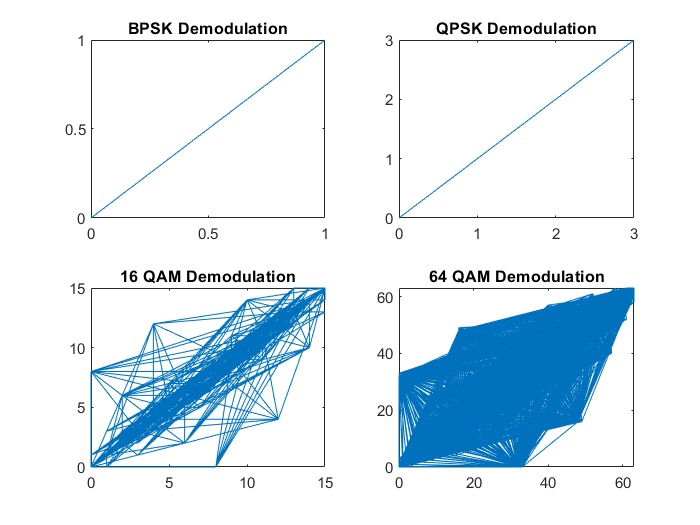

%BPSK
M = 2;
bpsk = pskdemod(bpsk_mod,M,0,'gray');


%QPSK
M = 4;
qpsk = pskdemod(qpsk_mod,M,pi/M,'gray');


%16QAM
M = 16;
qam16 = pskdemod(qam16_mod,M,pi/M,'gray');


%64QAM
M=64;
qam64 = pskdemod(qam64_mod,M,pi/M,'gray');


if (~enable_FEC)
    if enable_plots
figure
subplot(2,2,1,gca);
plot(bpsk,symbols_b);
title("BPSK Demodulation");
subplot(2,2,2);
plot(qpsk,symbols_q);
title("QPSK Demodulation");
subplot(2,2,3);
plot(qam16,symbols_16);
title("16 QAM Demodulation");
subplot(2,2,4);
plot(qam64,symbols_64);
title("64 QAM Demodulation");
    end
end

## Decode FEC

if enable_FEC
    
end